# Exercise 2

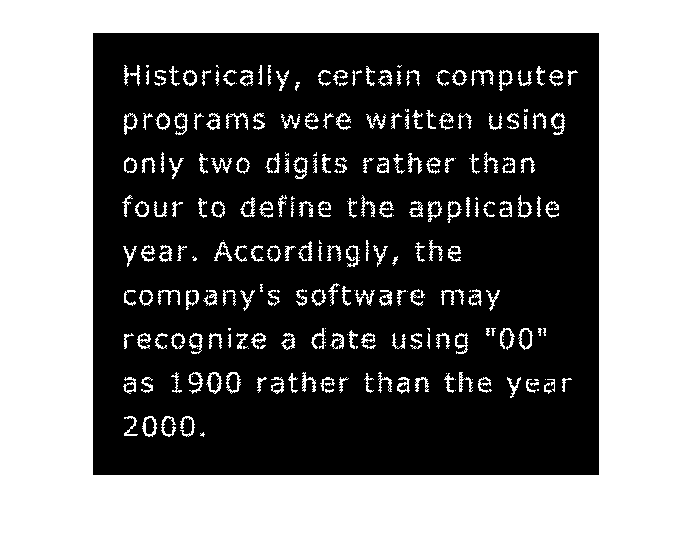

imoriginal=imread('broken-text.tif');
im = imoriginal;
imshow(im)

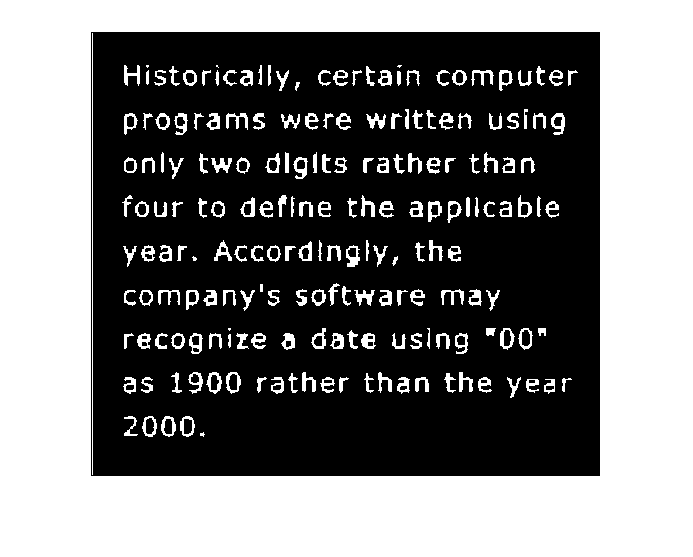


%closing on image
im=bwmorph(im,'close');
imshow(im)

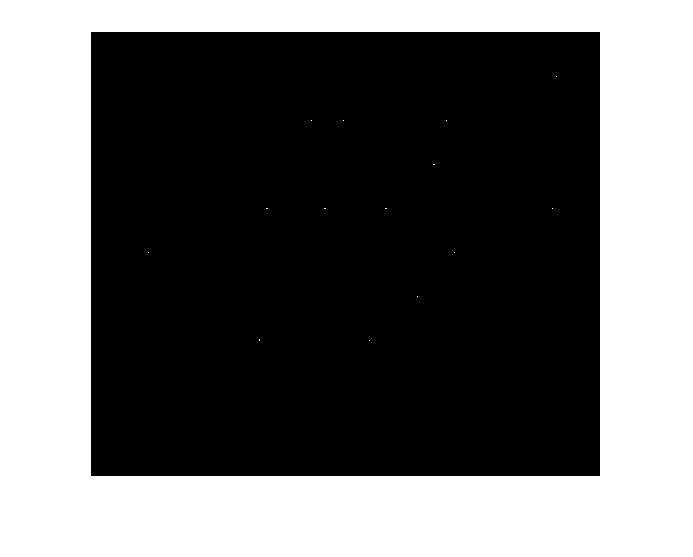



se =[
0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 0 0 0 1 1 1 1 1 0 0 0 0 0 0 ;
0 0 0 0 1 0 0 0 0 0 1 0 0 0 0 0 ;
0 0 0 1 0 0 0 0 0 0 0 1 0 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 1 1 1 1 1 1 1 1 1 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 0 0 0 1 1 0 0 0 0 0 0 0 0 0 ;
0 0 0 0 0 0 0 1 1 1 1 0 0 0 0 0 ;
0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 ];

%erode image, now only the origins of SE are left
im =imerode(im,se);
imshow(im);


%create a SE and dilate the origins of previous image
se=ones(18)

se =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1  

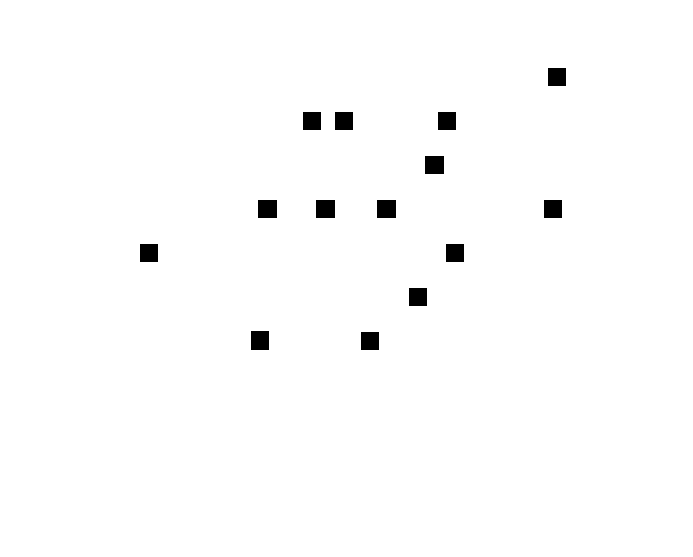

im2 = imdilate(im,se);
imshow(1-im2)


%combine this with the original image to remove the letters
im_gaps = imoriginal.*(1-im2)

im_gaps =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     0     0     0     0     0     0     0     0     0     0     0   

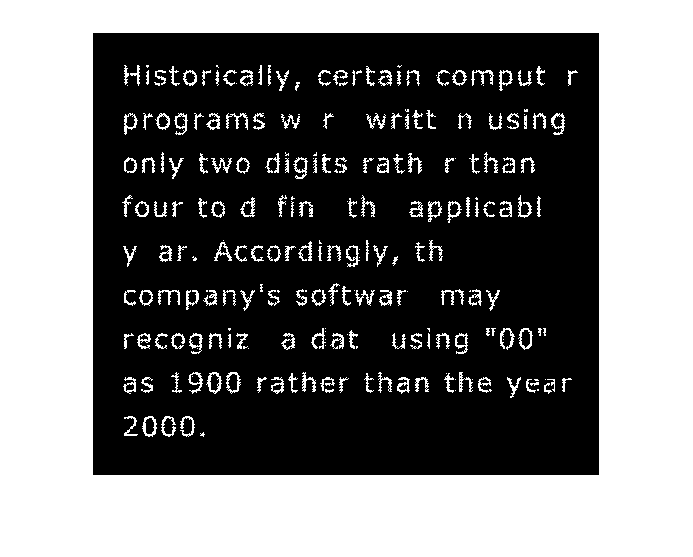

imshow(im_gaps)


se =[
0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 0 0 0 1 1 1 1 1 0 0 0 0 0 0 ;
0 0 0 0 1 0 0 0 0 0 1 0 0 0 0 0 ;
0 0 0 1 0 0 0 0 0 0 0 1 0 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 0 1 1 0 0 0 0 0 1 1 0 0 0 0 ;
0 0 0 0 0 1 1 0 0 1 0 0 0 0 0 0 ;
0 0 0 0 0 0 0 1 1 0 0 0 0 0 0 0 ;
0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 ];

%dilate with SE of letter O on the image with origins
im = imdilate(im,se)

im = 444×509 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

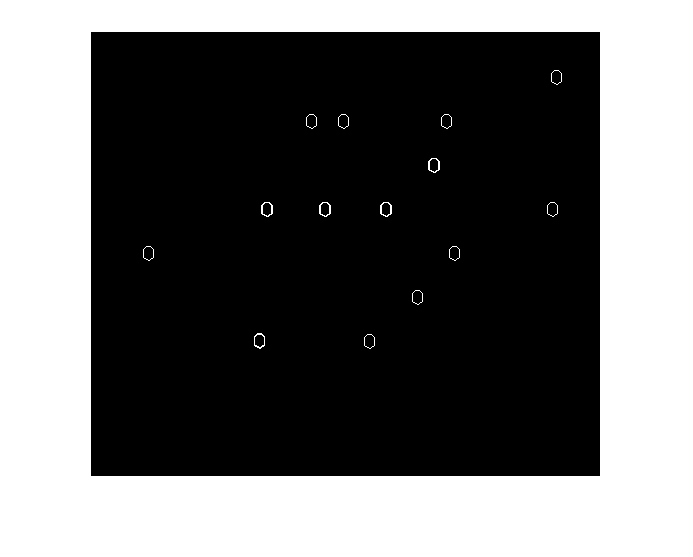

imshow(im)


%add the two together
im_result = im+im_gaps

im_result =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     0     0     0     0     0     0     0     0     0     0     0 

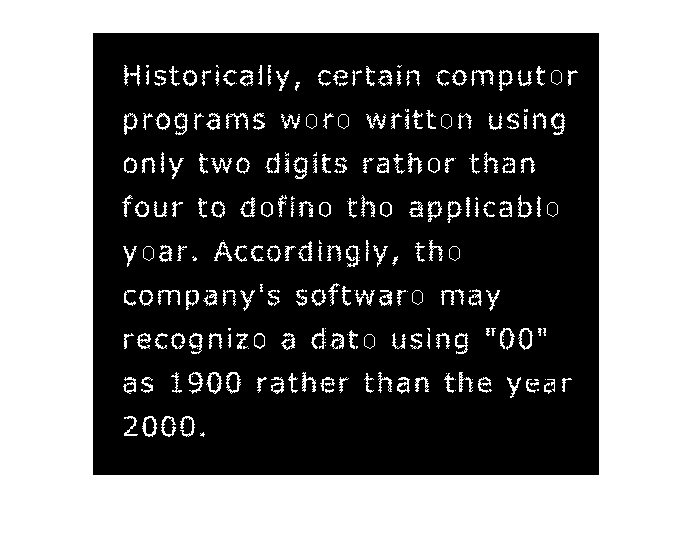

imshow(im_result)